# PV emulator curves

First, we are going to test the equations:


$$I=N_PI_{PH}-N_PI_S[e^{(q(V/N_S+iR_s/N_P)/kT_{cell}A)}-1]-(N_PV/N_S+iR_S)/R_{SH}$$


We want to plot the curves for different temperatures and different irradiation

for that we use the pv_math function, which is a script that  uses the samle mathematical model as what is implemented in the PV model simulink...

type pv_math.m

function I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i)
%     q = 1.6e-19;                          % Electron charge
%     k = 1.38e-23;                         % Boltzmann constant
%     Tcell = 273+T;                        % Cell temperature in Kelvin
% %     vt=(A*k*Tcell*Ns)/q;                  % Thermal voltage Equation(5)
%         
%     Isc_T = Isc+((Isc*(Ki/100))*(T-25));  % Isc temperature coef Equation(6)
%     Voc_T = Voc+((Voc*(Kv/100))*(T-25));  % Voc temperature coef Equation(7)
%     Is = Isc_T/(exp(Voc_T/((A*k*Tcell*Ns)/q))-1);         % Reverse saturation current Equation(8)
%     Iph = Isc_T*(G/1367);                 % Photon current Equation(9)
%     
%     % Single diode model output current Equation(4)
%     I = Np*Iph-Np*Is*( exp(q*(V/Ns+i*Rs/Np)/(k*Tcell*A) )  -1) -(Np*V/Ns+i*Rs)/Rsh ;
%     %I=Np*Iph-Np*Is*(exp(q*V/(Ns*k*Tcell*A))-1);


    q = 1.6e-19;                          % Electron charge
    k = 1.38e-23;                         % Boltzmann constan

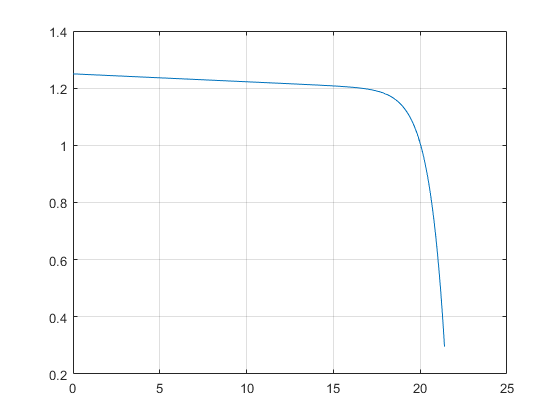

clear all
close all
G=1000;
T=25;
Isc=1.25;
Voc=21.7;
A=0.97;
Rs=1.3;
Rsh=362;
Ns=36;
Np=1;
k_i=0.102;
k_v=-0.36099;
i=0;
V=0:0.1:21.4;
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,k_i,k_v,V,i);
figure(1)
plot(V,I)
grid on

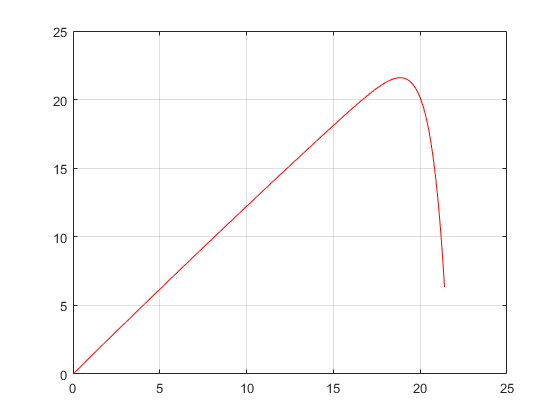

figure(2)
plot(V,V.*I,'r')
grid on

## IonSat 4S1P

Using the values of the MSP IonSat Solar panel, which has 4 blocks of 4S1P in parallel, which give in total 4S4P , The value of A is found from this article Tsai, H. L., Tu, C. S., & Su, Y. J. (2008, October). Development of generalized photovoltaic model using MATLAB/SIMULINK. In *Proceedings of the world congress on Engineering and computer science* (Vol. 2008, pp. 1-6).

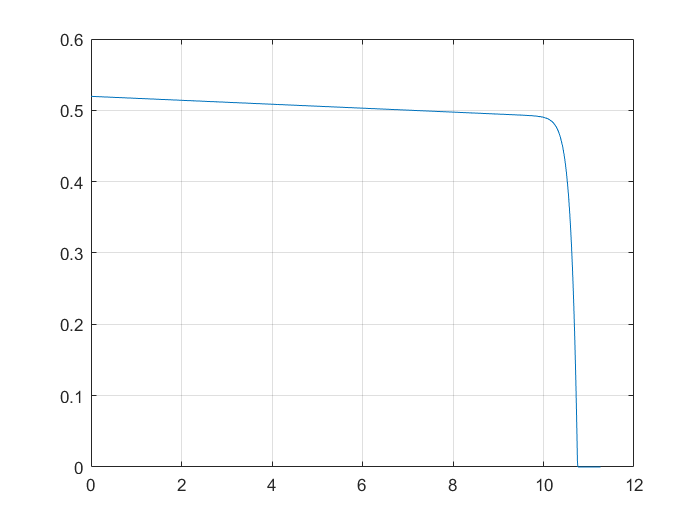

Ns=4;
Np=1;
G=1000;
T=25;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.01:Voc+0.5;
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
figure(3)
plot(V,I)
grid on

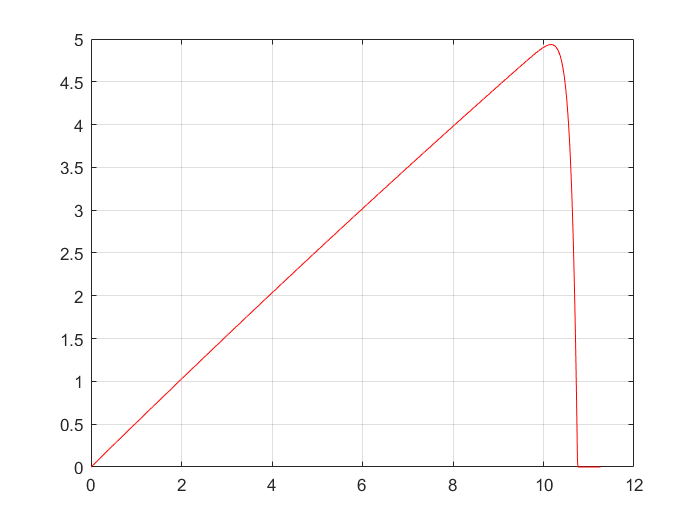

figure(4)
plot(V,V.*I,'r')
grid on

### Variation of Temperature

I-V

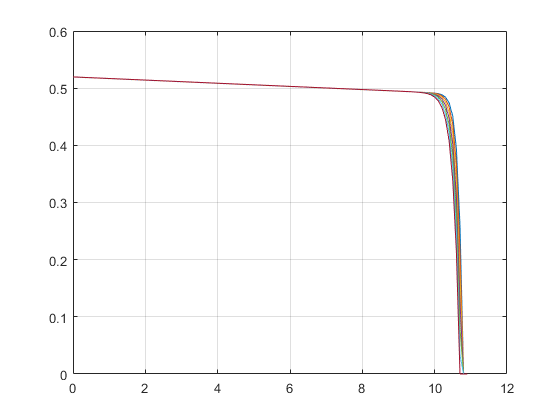

Ns=4;
Np=1;
G=1000;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc+0.21;
figure(5)
% for j = 1:1
%for j = 1:length(T)
for T=-20:20:100
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
plot(V,I)
hold on
grid on
end

P-V

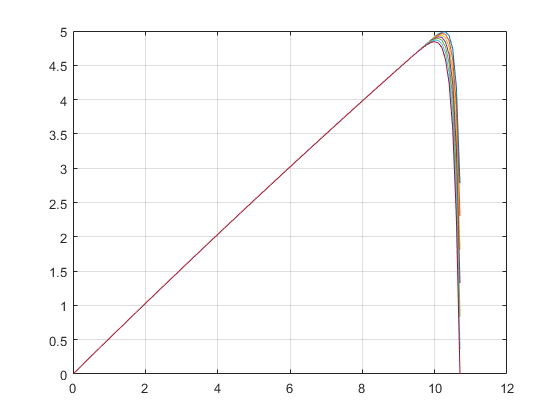

Ns=4;
Np=1;
G=1000;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc;
figure(6)
for T=-20:20:100
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
plot(V,V.*I)
hold on
grid on
end

### Variation with irradiance

I-V

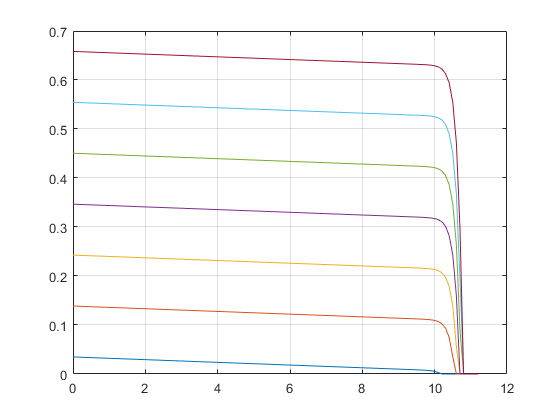

Ns=4;
Np=1;
T=25;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc+0.5;
figure(7)
for G=1367-1300:200:1367
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
plot(V,I)
hold on
grid on
end

P-V

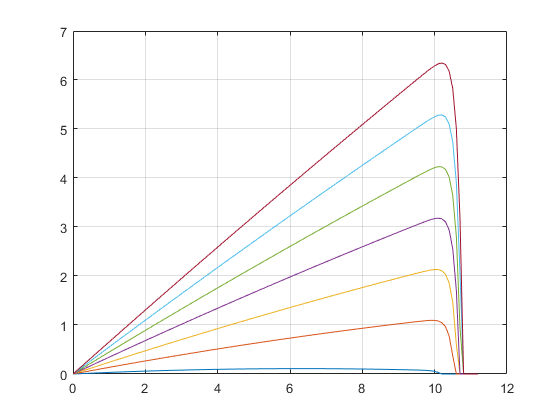

Ns=4;
Np=1;
T=25;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.1:Voc+0.5;
figure(8)
for G=1367-1300:200:1367
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
plot(V,I.*V)
hold on
grid on
end

# DC-DC buck converter

We want to check if the component values provided by the reference are good enough for our new design of the PV emulator, first we check what are the ΔI and ΔV for the original case, also assuming a D=0.74, given a source voltage of 24V.

L=1e-3;
C=4700e-6;
Vin=24;
Vout=17.78;
F=3921.16;
D=Vout/Vin

D = 0.7408

DV=(Vin*(1-D)*D)/(8*C*L*F^2)

DV = 0.0080

DI=(Vin*(1-D)*D)/(L*F)

DI = 1.1752

## IonSat 

For the case of IonSat, D=0.89 becuase the Input voltage will be around 12V.

We can check that  ΔV is also small, so the same component values will work.

L=1e-3;
C=4700e-6;
Vin=12;
Vout=10.7;
F=3921.16;
D=Vout/Vin

D = 0.8917

DV=(Vin*(1-D)*D)/(8*C*L*F^2)

DV = 0.0020

DI=(Vin*(1-D)*D)/(L*F)

DI = 0.2956

## Calculating the value of Rload

We are testing what are the values of the load to check the different (I,V) points of the PV emulator.

To do so, first, we are going to use the I and V values of different points of the IV desired curve. We know this will intersect with the value of the Rload, so, a proposal could be to use to resistances in series, R1 & R2, with another one in parallel, R3, so, the total equivalent load would be: 

Rload = (R1+R2) || R3.

R1 is the variable resistance that we have, this variable resistance has a maximum dissipation power of 0.6W, so this is a first condition.

It is possible to fix R2 with other values (R2 will limit the current on R1, so it limits the dissipation power, it has to be close to R1) so R3 is defined with the previous constants. In the following calculation, two outputs are interesting: What is the value of R3? and what is the dissipation P1? 

close all
I=0.3;
V=9.9;
R1=10;
R2=30;
[RL,R3,I1,P1,P2,P3] = TESTR3(R1,R2, I, V)

RL = 33

R3 = 188.5714

I1 = 0.2475

P1 = 0.6126

P2 = 1.8377

P3 = 0.5197

Now that R3 is fixed, we can start make variations on R1, to see what is the range of Rload that can be produced.

First, it is necessary to check that the dissipation power on R1 does not exceed the 0.5W (0.1W of margin) of dissipation from R1. When the dissipation power P1 reaches 0.5, that would be the maximum that R1 can reach.

Then, the variation of R1 will also affect Rload, this will produce a range of values that can be used to get different values of V and I in the IV curve of the emulator.

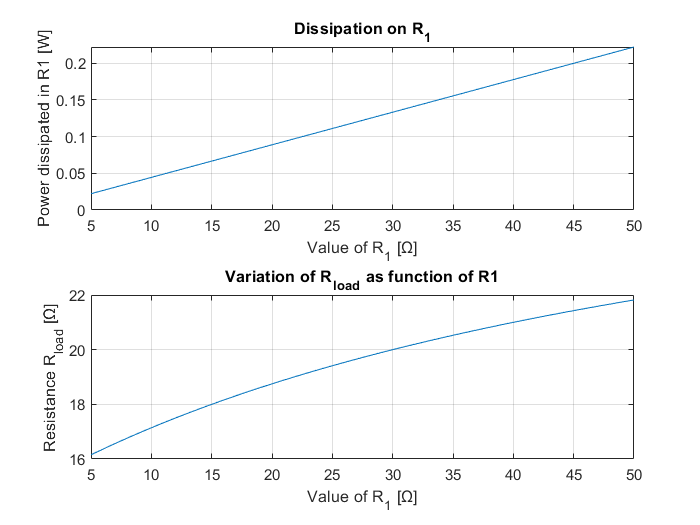

R3=27;
R1=5:1:50;
[RL,I1,P1,P2,P3] = testRL(R1,R2,R3,I,V);
figure(9)
subplot(2,1,1)
plot(R1,P1)
hold on
grid on
title('Dissipation on R_1')
xlabel('Value of R_1 [Ω]')
ylabel('Power dissipated in R1 [W]')
subplot(2,1,2)
R3=30;
RL=(R1+R2).*R3./(R1+R2+R3);
plot(R1,RL)
hold on
grid on
title('Variation of R_{load} as function of R1')
xlabel('Value of R_1 [Ω]')
ylabel('Resistance R_{load} [Ω]')

### Value of Rload for Peak Power

In the case of peak power:

I=0.483;
V=10.2;
P_peak=I*V

P_peak = 4.9266

R1=20;
R2=50;
[RL,R3,I1,P1,P2,P3] = TESTR3(R1,R2, I, V)

RL = 21.1180

R3 = 30.2414

I1 = 0.1457

P1 = 0.4247

P2 = 1.0616

P3 = 3.4403

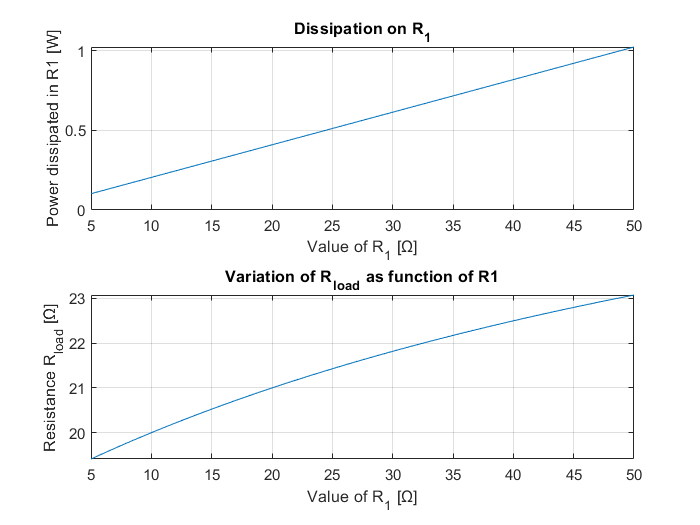

R3=30;
R1=5:1:50;
[RL,I1,P1,P2,P3] = testRL(R1,R2,R3,I,V);
figure(10)
subplot(2,1,1)
plot(R1,P1)
hold on
grid on
title('Dissipation on R_1')
xlabel('Value of R_1 [Ω]')
ylabel('Power dissipated in R1 [W]')
subplot(2,1,2)
R3=30;
RL=(R1+R2).*R3./(R1+R2+R3);
plot(R1,RL)
hold on
grid on
title('Variation of R_{load} as function of R1')
xlabel('Value of R_1 [Ω]')
ylabel('Resistance R_{load} [Ω]')

### Other values of Rload

In other cases:

I=0.49;
V=9.9;
P_peak=I*V

P_peak = 4.8510

R1=20;
R2=100;
[RL,R3,I1,P1,P2,P3] = TESTR3(R1,R2, I, V)

RL = 20.2041

R3 = 24.2945

I1 = 0.0825

P1 = 0.1361

P2 = 0.6806

P3 = 4.0343

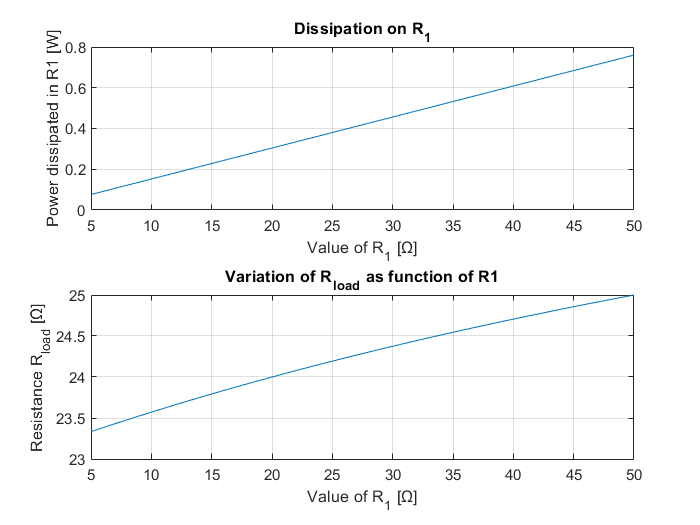

R3=27;
R1=5:1:50;
[RL,I1,P1,P2,P3] = testRL(R1,R2,R3,I,V);
close all
figure(11)
subplot(2,1,1)
plot(R1,P1)
hold on
grid on
title('Dissipation on R_1')
xlabel('Value of R_1 [Ω]')
ylabel('Power dissipated in R1 [W]')
subplot(2,1,2)
R3=30;
RL=(R1+R2).*R3./(R1+R2+R3);
plot(R1,RL)
hold on
grid on
title('Variation of R_{load} as function of R1')
xlabel('Value of R_1 [Ω]')
ylabel('Resistance R_{load} [Ω]')

## Resistance vs curve

Using the values of the MSP IonSat Solar panel, which has 4 blocks of 4S1P in parallel, which give in total 4S4P , The value of A is found from this article Tsai, H. L., Tu, C. S., & Su, Y. J. (2008, October). Development of generalized photovoltaic model using MATLAB/SIMULINK. In *Proceedings of the world congress on Engineering and computer science* (Vol. 2008, pp. 1-6).

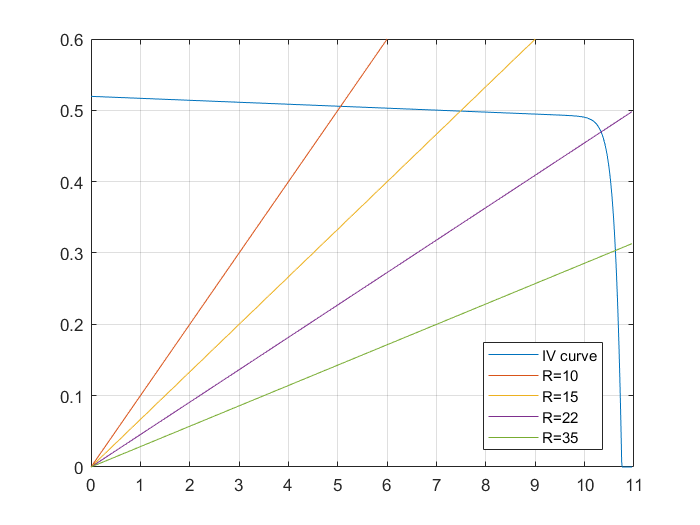

clear all

Ns=4;
Np=1;
G=1000;
T=25;
Isc=0.5196; %cell
Voc=Ns*2.69; %array
A=1.3;
Rs=1.3;
Rsh=362;
Ki=0.36e-3;
Kv=-6.7e-3;
i=0;
V=0:0.01:Voc+0.2;
I = pv_math(G,T,Isc,Voc,A,Rs,Rsh,Ns,Np,Ki,Kv,V,i);
R10=10;
R15=15;
R22=22;
R35=35;

figure(12)
plot(V,I)
hold on
plot(V,V/R10)
plot(V,V/R15)
plot(V,V/R22)
plot(V,V/R35)
grid on
xlim([0 11])
ylim([0 0.6])
legend('IV curve','R=10','R=15','R=22','R=35','Location',"best")

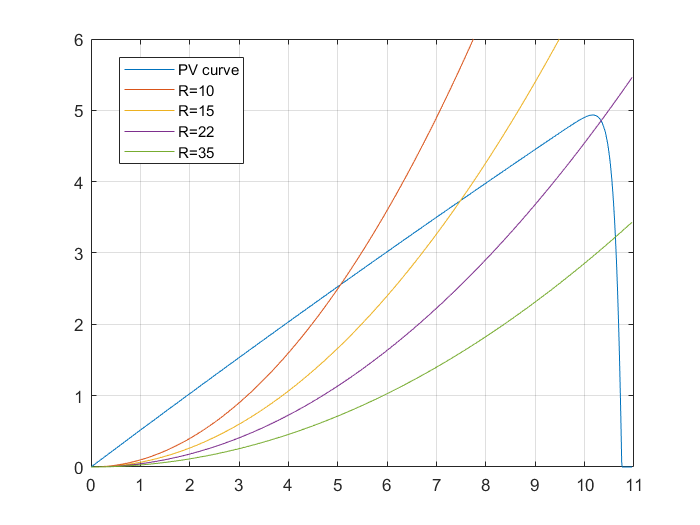

figure(13)
plot(V,I.*V)
hold on
plot(V,V.^2/R10)
plot(V,V.^2/R15)
plot(V,V.^2/R22)
plot(V,V.^2/R35)
grid on
xlim([0 11])
ylim([0 6])
legend('PV curve','R=10','R=15','R=22','R=35','Location',"best")